# ROZWIĄZAYWANIE UKŁADÓW RÓWNAŃ LINIOWYCH

## Metoda Jakobiego - warunki zbieżności

Każda metoda iteracyjna była budowana z myślą o pewnej klasie układów równań liniowych dla których jest zbieżna. W przypadku metody Jakobiego warunkiem koniecznym i wystarczającym zbieżności tego procesu iteracyjnego jest, aby macierz** A** była nieredukowalna i diagonalnie słabo dominująca.

Każda metoda ma tego typu opis to nie zawsze znaczy, że jest zbieżna tylko dla danej klasy macierzy (układów równań), ale gwarantuje zbieżność dla tej klasy.

Poniższy skrypt z poprzedniego zadania zawiera macierz diagonalnie silnie dominującą. 

1. Uruchom go z ustawieniem "Redraw plot" i zwróć uwagę, na wypisany promień spektralny macierzy ***M***

2. Pamiętając, że warunek zbieżności metody to:


$$\varrho \left(\mathit{\mathbf{M}}\right)<1$$


spróbuj zdestabilizować metodę przez uczynienie macierzy ***A*** diagonalnie niedominującą. Zobacz, że dla takich danych metoda iteracyjna nie jest zbieżna.

3. Przestaw przełącznik na AddPlot - zmieniaj macierz ***A*** tak, aby stawała się coraz bardziej silnie diagonalnie dominująca - zaobserwuj jak promień spektralny wypisany obok ma się do szybkości zbieżności metody

%Czyszczenie
clear all;clc;

% Najpierw zdefiniujmy przykładowy układ równań:
A=[115 -2 3 0 6;...
   -3 19 1 -2 7.4;...
   2 -1 -157 1 6.7;...
   4 3 -5 117 9;...
   2 3.5 6.1 -4 -118.1];
b=[-1 2 3 0.5 43.1]';

% Dokonajmy teraz rozkładu macierzy A wg schematu metody Jakobiego
% uzyskując macierz M i wektor w
D=diag(diag(A));
L=tril(A)-D;
U=triu(A)-D;

M=-pinv(D)*(L+U);
w=pinv(D)*b;

spectrumM = abs(max(eig(M)));

%Przyjęcie parametrów dla algorytmu iteracyjengo 

%-> punkt startowy - losowy
x0=rand(numel(b),1);

%-> wymagana dokłaność
delta0 = 1e-8;

%-> maksymalna ilość iteracji
i_max = 50;

%Implementacja metody Jakobiego
i=1;     %licznik iteracji 
error=5*delta0;
x_old=x0;
x=x_old; %wektor rozwiązań w kolejnych iteracjach;
n=i;     %wektor numerów iteracji do rysowania
err = [];%wektor błędów do rysowania
while( (error>=delta0) & (i<i_max))
    x_new = M*x(:,end)+w;
    error = norm(x_new-x_old);  %obliczenie esymaty błędu
    x_old=x_new;
    x=[x x_new]; 
    
    err=[err error];  
    n=[n i];i = i+1;
    
end

%Rysowanie błędu
fprintf("Promień spektralny macierzy M: %0.2f\n", spectrumM);

Promień spektralny macierzy M: 0.12


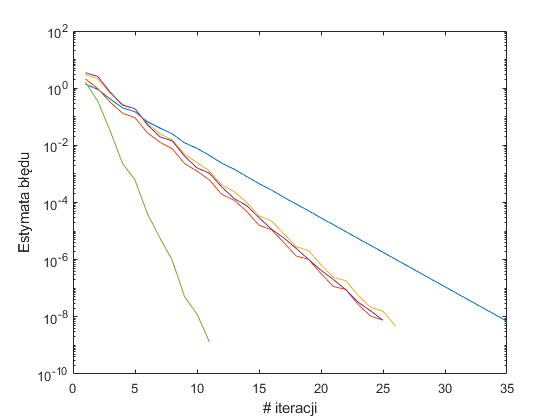

semilogy(n, [err(1) err]);xlabel("# iteracji");ylabel("Estymata błędu");
hold on;